rng default
samples = 1000000

samples = 1000000

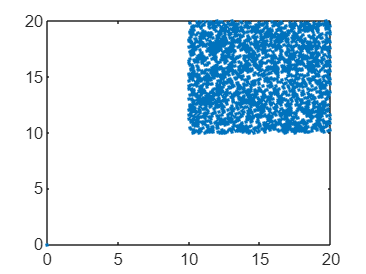

xq = sizes.* rand(samples,1)+10;
yq = sizes.* rand(samples,1)+10;
%%[in,on] = inpolygon(xq,yq,bots(1).verts(1,:),bots(1).verts(2,:));
quad_vertex = [10 10; 10 20; 20 20; 20 10];
[in,on] = inpolygon(xq,yq,quad_vertex(:,1),quad_vertex(:,2));
plot(in.*xq,in.*yq,'.');

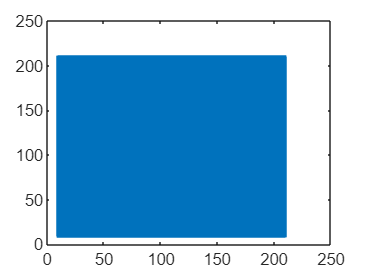

plot(xq,yq,'.');

area=(numel(xq(in))+numel(xq(on)))/samples*sizes^2

area = 102.6000

xc = ((sizes^2/area)/samples)*(sum(xq(in)+sum(xq(on))))

xc = 14.9415

yc = ((sizes^2/area)/samples)*sum(yq(in)+sum(yq(on)))

yc = 14.9869

[x,y]=centroid(polyshape(quad_vertex))

x = 15

y = 15

polyg = polyshape(bots(1).verts(1,:),bots(1).verts(2,:))

polyg =   polyshape with properties:

      Vertices: [31×2 double]
    NumRegions: 1
      NumHoles: 0


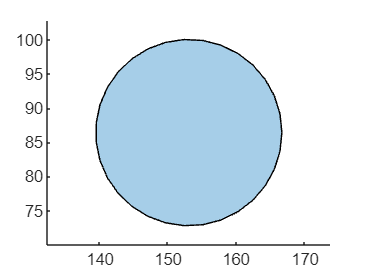

plot(polyg)
axis equal

xx=[0;0]

xx =      0
     0


clear area
area(polyg)

ans = 580.1889

[a,b]=centroid(polyg)

a = 153.0501

b = 86.4054

MC_int_2D(20,bots(1).pos,bots(1).verts)

ans =   399.0000  153.0666   86.3225



rng default
samples = 10000

samples = 10000

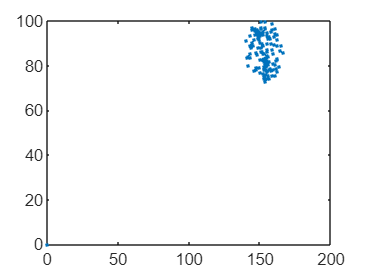

xq = sizes.* rand(samples,1)+a-sizes/2;
yq = sizes.* rand(samples,1)+b-sizes/2;
[in,on] = inpolygon(xq,yq,bots(1).verts(1,:),bots(1).verts(2,:));
plot(in.*xq,in.*yq,'.');

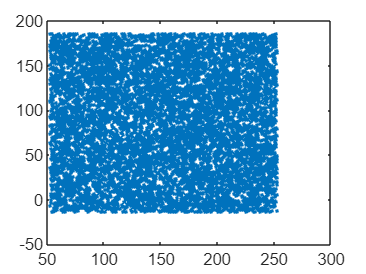

plot(xq,yq,'.');

area=(numel(xq(in))+numel(xq(on)))/samples*sizes^2

area = 508

xc = ((sizes^2/area)/samples)*(sum(xq(in)+sum(xq(on))))

xc = 153.2465

yc = ((sizes^2/area)/samples)*sum(yq(in)+sum(yq(on)))

yc = 86.6204

mu = [0 0];
Sigma = [0.25 0.3; 0.3 1];
x1 = -3:0.2:3;
x2 = -3:0.2:3;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];
y = mvnpdf(X,mu,Sigma);
y = reshape(y,length(x2),length(x1))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0010    0.0020    0.0033    0.0043    0.0043    0.0033    0.0020    0.0010    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0030    0.0053    0.0073    0.0079    0.0066    0.0043    0.0022    0.0009    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0005    0.0017    0.0041    0.0078    0.0116    0.0135    0.0122    0.0086    0.0047    0.0020    0.0007    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   

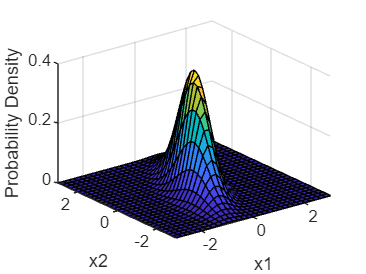

surf(x1,x2,y)
axis([-3 3 -3 3 0 0.4])
xlabel('x1')
ylabel('x2')
zlabel('Probability Density')

a=random_rect(50)

a =    10.9739   11.0739   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232   11.1232
   19.4045   19.4045   19.4045   19.5045   19.6045   19.7045   19.8045   19.9045   20.0045   20.1045   20.2045   20.3045   20.4045   20.5045   20.6045   20.7045   20.8045   20.9045   21.0045   21.1045   21.2045   21.3045   21.4045   21.5045   21.6045   21.7045   21.8045   21.9045   22.0045   22.1045   22.2045   22.3045   22.4045   22.5045   22.6045   22.7045   22.8045   22.9045   23.0045   23.1045   23.2045   23.3045   23.4045   23.5045   23.6045   23.7045   23.8045   23.9045   24.0045   24

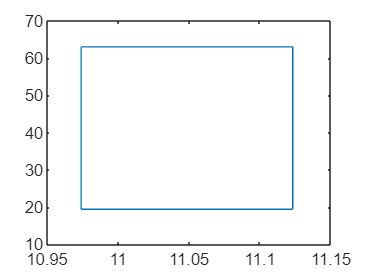


figure
plot(a(1,:),a(2,:))



bots(1).obstacles_in_polar


ans =

     []



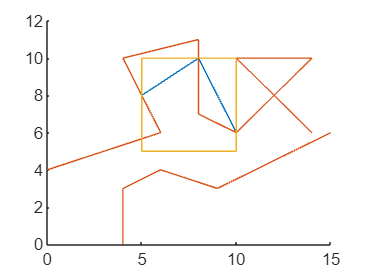

x = [0 6  4  8 8 10 14 10 14 NaN 4 4 6 9 15];
y = [4 6 10 11 7  6 10 10  6 NaN 0 3 4 3  6];
x1 = [5 5 10 10 5];
y1 = [5 10 10 5 5];
[xi,yi] = polyxpoly(x,y,x1,y1);
figure
hold on
plot(xi,yi);
plot(x,y);
plot(x1,y1);

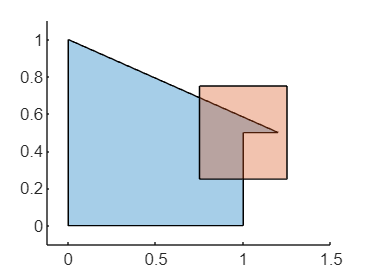

poly1 = polyshape([0 0 1 1 1.2],[1 0 0 0.5 0.5]);
poly2 = polyshape([0.75 1.25 1.25 0.75],[0.25 0.25 0.75 0.75]);
figure
hold on
plot(poly1)
plot(poly2)

polyout = intersect(poly1,poly2)

polyout =   polyshape with properties:

      Vertices: [5×2 double]
    NumRegions: 1
      NumHoles: 0


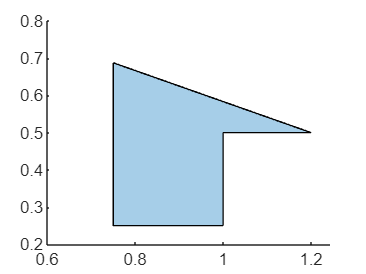

figure
plot(polyout)


%%circle = polyshape(bots(5).pos(1,1)+15.*cos([0:0.1:2*pi]),bots(5).pos(2,1)+15.*sin([0:0.1:2*pi]))
poly1 = polyshape([bots(3).pos(1,1),bots(3).obst(1,:)],[bots(3).pos(2,1),bots(3).obst(2,:)]);

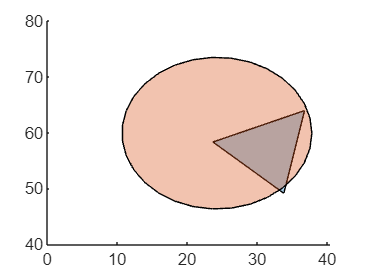

poly2 = polyshape(bots(3).verts_unc(1,:),bots(3).verts_unc(2,:));
figure 
hold on
plot(poly1)
plot(poly2)




a=bots(3).vertex_obst;
poly3 = polyshape(a(1,:),a(2,:));

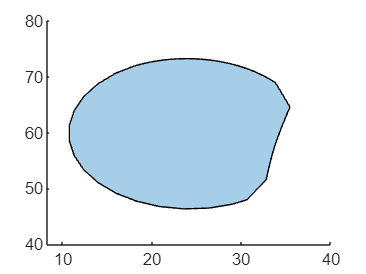

figure
plot(intersect(poly3,poly2));

ob=build_obst([10,20,30,35,20;10,10,20,40,60],100)

ob =    10.0000   10.0100   10.0200   10.0300   10.0400   10.0501   10.0601   10.0701   10.0801   10.0901   10.1001   10.1101   10.1201   10.1301   10.1401   10.1502   10.1602   10.1702   10.1802   10.1902   10.2002   10.2102   10.2202   10.2302   10.2402   10.2503   10.2603   10.2703   10.2803   10.2903   10.3003   10.3103   10.3203   10.3303   10.3403   10.3504   10.3604   10.3704   10.3804   10.3904   10.4004   10.4104   10.4204   10.4304   10.4404   10.4505   10.4605   10.4705   10.4805   10.4905
   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   1

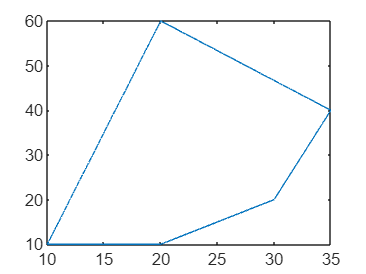


plot(ob(1,:),ob(2,:))

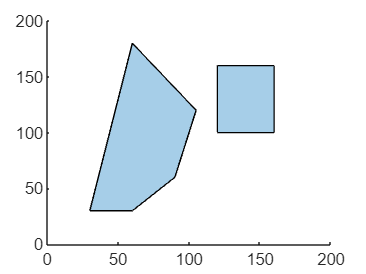



plot(union(poly_obstacles{: ...
    }))

xc=55;
yc=182;
bots(2).steps_vert = 101;

rad = 30/2.2

rad = 13.6364

%%bots(2).rs=30/2.2;
update_obstacles(obstacles,bots);
pp=bots(2).vertex_unc2

pp =    13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364   13.6364
         0    0.0622    0.1244    0.1866    0.2488    0.3110    0.3733    0.4355    0.4977    0.5599    0.6221    0.6843    0.7465    0.8087    0.8709    0.9331    0.9954    1.0576    1.1198    1.1820    1.2442    1.3064    1.3686    1.4308    1.4930    1.5552    1.6175    1.6797    1.7419    1.8041    1.8663    1.9285    1.9907    2.0529    2.1151    2.1773    2.2396    2.3018    2.3640    2.4262    2.4884    2.5506    2.6128    2.6750    2.7372    2.7994    2.8616    2.9239    2.9861    

[b,a]=lidar_sim(obstacles,[xc;yc],rad)

b =    13.6318   13.6220   13.6123   13.6025   13.5927   13.5829   13.5731   13.5633   13.5535   13.5437   13.5340   13.5242   13.5144   13.5046   13.4948   13.4850   13.4753   13.4655   13.4557   13.4459   13.4361   13.4263   13.4166   13.4068   13.3970   13.3872   13.3774   13.3677   13.3579   13.3481   13.3383   13.3285   13.3188   13.3090   13.2992   13.2894   13.2797   13.2699   13.2601   13.2503   13.2406   13.2308   13.2210   13.2112   13.2015   13.1917   13.1819   13.1721   13.1624   13.1526
    5.5628    5.5629    5.5631    5.5632    5.5634    5.5635    5.5637    5.5638    5.5640    5.5641    5.5643    5.5644    5.5646    5.5647    5.5649    5.5650    5.5652    5.5654    5.5655    5.5657    5.5658    5.5660    5.5661    5.5663    5.5664    5.5666    5.5668    5.5669    5.5671    5.5672    5.5674    5.5675    5.5677    5.5679    5.5680    5.5682    5.5683    5.5685    5.5687    5.5688    5.5690    5.5691    5.5693    5.5695    5.5696    5.5698    5.5699    5.5701    5.5703    5

a =    13.6042   13.4477   13.2916   13.1450   12.9987   12.8528   12.7162   12.5800   12.4441   12.3175   12.1913   12.0653   11.9397   11.8233   11.7072   11.5914   11.4847   11.3784   11.2723   11.1665   11.0610   10.9645   10.8683   10.7724   10.6767   10.5814   10.4949   10.4087   10.3227   10.2370   10.1515   10.0663    9.9899    9.9137    9.8377    9.7620    9.6865    9.6112    9.5363    9.4698    9.4036    9.3294    9.2636    9.1981    9.1328    9.0758    9.0110    8.9463    8.8900    8.8339
    4.9148    4.9197    4.9247    4.9296    4.9346    4.9396    4.9445    4.9494    4.9545    4.9594    4.9643    4.9693    4.9745    4.9794    4.9843    4.9894    4.9942    4.9990    5.0040    5.0090    5.0142    5.0190    5.0239    5.0289    5.0339    5.0391    5.0438    5.0487    5.0536    5.0586    5.0637    5.0689    5.0737    5.0785    5.0834    5.0883    5.0934    5.0985    5.1037    5.1084    5.1131    5.1186    5.1235    5.1284    5.1335    5.1379    5.1431    5.1484    5.1530    5

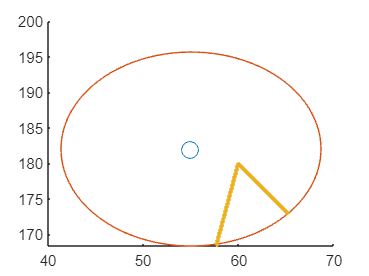

figure 
hold on
plot(xc,yc,'o',MarkerSize=10)
plot(xc+rad.*cos(linspace(0,2*pi,100)),yc+rad.*sin(linspace(0,2*pi,100)))
plot(xc+b(1,:).*cos(b(2,:)),yc+b(1,:).*sin(b(2,:)),'.')

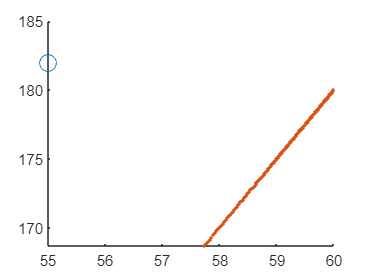



figure
hold on
plot(xc,yc,'o',MarkerSize=10)
plot(xc+a(1,:).*cos(a(2,:)),yc+a(1,:).*sin(a(2,:)),'.')

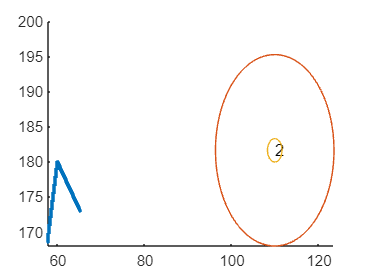


figure
hold on
plot(xc+b(1,:).*cos(b(2,:)),yc+b(1,:).*sin(b(2,:)),'.')
bots(2).plot_bot

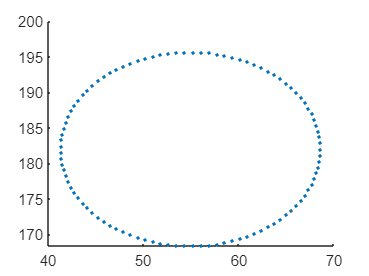


figure
hold on
plot(xc+pp(1,:).*cos(pp(2,:)),yc+pp(1,:).*sin(pp(2,:)),'.')

c= [0,1.955,2.04,3,4,5];
h=[];
for i = 1:5
    candidates=find(abs(c-i)<0.05);
    if ~isempty(candidates)
        [~,indx]=min(abs(c(candidates)-i));
        indx=candidates(indx)
        h = [h,c(indx)];
    end
end

kl=polyshape([a(1,:).*cos(a(2,:)),45],[a(1,:).*sin(a(2,:)),30])